# 使用分支定界法求解整数规划

## 测试用例

使用课本P107例1演示


$$$L_0:max$ $z=3x_1+2x_2$$$



$$s\ldotp t\ldotp \left\lbrace \begin{array}{ll}
2x_1 +3x_2 \le 14 & \\
x_1 +0\ldotp 5x_2 \le 4\ldotp 5 & 
\end{array}\right.$$


c=[-3,-2]';
A=[2,3;1,0.5];
b=[14,4.5]';
[optSolution,optValue,exists,hist]=BranchBound(c,A,b); % 求解

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


No feasible solution found.

Linprog stopped because no point satisfies the constraints.


Optimal solution found.



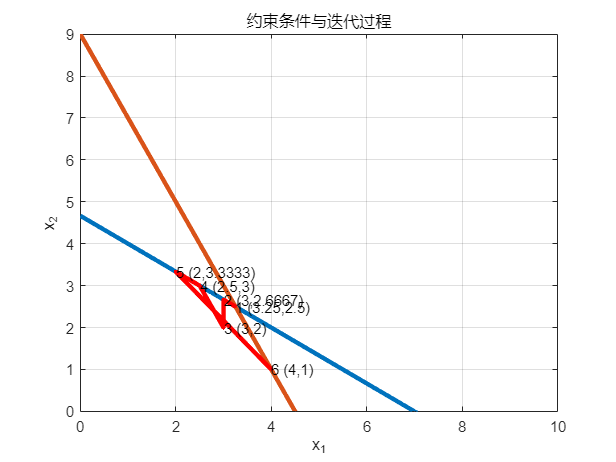

Draw(hist,A,b); % 绘图

## 函数定义

### 运算函数

function [optSolution,optValue,exists,hist]=BranchBound(c,A,b)
%% 格式要求如下（运算主体是Matlab自带的求解器函数linprog）：
% min c'*x；c是个列向量，如果为max将c自乘-1
% s.t.
% A*x<=b；默认约束条件为\leq，若有\geq则将对应行的A(i,j)和b(i)自乘-1

hist=[];
upper = inf;
lower = -inf;
branchStack_A(1) = {A};
branchStack_B(1) = {b};
numOfVariable = length(c);
 
while ~isempty(branchStack_A)
    len = length(branchStack_A);
    A = branchStack_A{len};
    b = branchStack_B{len};
    branchStack_A(len) = [];
    branchStack_B(len) = [];

    [x,opt,exist] = linprog(c,A,b);
    hist=[hist;x'];
    % 是否迭代的判断条件
    if 1 == exist && (opt - upper) <= 1e-7
        for iVar = 1:numOfVariable + 1
            if iVar <= numOfVariable
                if abs(x(iVar) - round(x(iVar))) > 1e-7
                    %进行分枝操作，就将子问题入栈
                    temp_A = zeros(1,numOfVariable);
                     
                    temp_A(iVar) = -1;
                    branchStack_A(len) = {[A;temp_A]};
                    branchStack_B(len) = {[b;-(floor(x(iVar) + 1))]};
                     
                    temp_A(iVar) = 1;
                    branchStack_A(len + 1) = {[A;temp_A]};
                    branchStack_B(len + 1) = {[b;floor(x(iVar))]};
                    break;
                end
            else
                %是个整数解.更新upper
                if abs(upper - opt) < 1e-7
                    optSolution(:,end + 1) = x;
                else
                    optSolution = x;
                    upper = opt;
                    optValue = opt;
                end
            end
        end
    end
end
    
sizeOfSolution = size(optSolution);
if sizeOfSolution(2) == 0
    exists = 0;
else
    exists = 1;
end
end 

### 绘图函数

function Draw(hist,A,b)
% hist:迭代点的迭代过程，每行为一个点
% A,b:定义同BranchBound()
x1=0:0.05:10;
x2=zeros(length(b),length(x1));
% 画约束条件
for i=1:length(b)
    x2(i,:)=(b(i)-A(i,1).*x1)./A(i,2); % 根据Ax<=b求解对应的x(2)
    plot(x1,x2(i,:),'LineWidth',3);
    axis([0 max(x1) 0 max(max(x2))]);
    hold on;
end
% 画迭代点
plot(hist(:,1),hist(:,2),'r.-','LineWidth',3);
hold on;
for i=1:size(hist,1)
    text(hist(i,1),hist(i,2),int2str(i)+" ("+num2str(hist(i,1))+","+num2str(hist(i,2))+")","FontSize",10);
end
% 做点修饰
title("约束条件与迭代过程");
xlabel('x_1');
ylabel('x_2');
grid;
hold off;
end